# Notebook 03: ANN Training

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 03**. Before running this notebook, you should have run Notebook 02 to generate features from the neural data.

## Step 0: Ensure you are in the correct directory

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Step 1: Load the neural features

Before proceeding, ensure you've run the last cell of the Feature Extraction section in `notebook 02`, which saves your neural features to the `results` folder in your workspace.

clearvars
load("datasets\training_dataset.mat")
load("results\features_binned.mat")
load("results\features_SES.mat")
load("results\features_RMS.mat")
load("results\features_ZC.mat")
load("results\features_ZCR.mat")
load("results\features_combo.mat")

## Step 2: Determine the dimensions of the mapping

For this section, you have been provided with a Multilayer Feedforward Network. You are welcome to use your own architecture, but the explanations in this notebook only apply to the provided network.

Remember that a neural network can be thought of as a [universal function approximator.](https://www.cs.cmu.edu/~epxing/Class/10715/reading/Kornick_et_al.pdf) This means that your network learns a one-to-one mapping between your input vectors and your output vectors:


$$\vec{x_{out}} = f(\vec{x_{in}})$$


For this reason, you must ensure that the network has the same number of input vectors as output vectors during training.

Your output vectors are the hand's kinematics, which are a set of `N` vectors with dimensionality `1x2.`

Your input vectors are a set of `N` vectors with dimensionality `1xM`, where `M` is determined by your feature extraction methods.

`N,` in this case, corresponds to the number of samples in the `hand_kinematics` of the training set.

First, verify that your have the same number of samples for the features and the kinematics, which will act as our feature labels (i.e., the values we are trying to predict).  

feature_labels = training_data.hand_kinematics;

% Save our features in variables
features_binned = neural_features_binned;
features_SES = neural_features_SES;
features_RMS = neural_features_RMS;
features_ZC = neural_features_ZC;
features_ZCR = neural_features_ZCR;
features_combo = neural_features_combo;

% Check all of our feature extraction methods
assert(length(features_binned) == length(feature_labels));
assert(length(features_SES) == length(feature_labels));
assert(length(features_RMS) == length(feature_labels));
assert(length(features_ZC) == length(feature_labels));
assert(length(features_ZCR) == length(feature_labels));
assert(length(features_combo) == length(feature_labels));

How many outputs do we want? Well, that depends on the number of degrees of freedom we are predicting, which in our case is:

n_outputs = width(feature_labels)

n_outputs = 2

How many features per sample do you have in total? That depends on the choices you made in `notebook_02`, including but not limited to:

- How many channels (out of the six provided in the dataset) you decided to use

- How many features per channel you calculated

%Add number calculations for our features
n_features_binned = width(features_binned)

n_features_binned = 18

n_features_SES= width(features_SES)

n_features_SES = 6

n_features_RMS = width(features_RMS)

n_features_RMS = 6

n_features_ZC = width(features_ZC)

n_features_ZC = 6

n_features_ZCR = width(features_ZCR)

n_features_ZCR = 6

n_features_combo = width(features_combo)

n_features_combo = 30

How many timestamps are there?

n_timestamps = length(feature_labels);

After providing this information, we know that **for every timestamp** in features:

fprintf('Binned features map a %dx1 vector to a %dx1 vector', n_features_binned, n_outputs)

Binned features map a 18x1 vector to a 2x1 vector


fprintf('SES features map a %dx1 vector to a %dx1 vector', n_features_SES, n_outputs)

SES features map a 6x1 vector to a 2x1 vector


fprintf('RMS features map a %dx1 vector to a %dx1 vector', n_features_RMS, n_outputs)

RMS features map a 6x1 vector to a 2x1 vector


fprintf('ZC features map a %dx1 vector to a %dx1 vector', n_features_ZC, n_outputs)

ZC features map a 6x1 vector to a 2x1 vector


fprintf('ZCR features map a %dx1 vector to a %dx1 vector', n_features_ZCR, n_outputs)

ZCR features map a 6x1 vector to a 2x1 vector

## Step 3: Implement and train the neural network

### A) Reshape input features

Due to MATLAB's limited selection of [input layers](https://www.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html), we will be using the [`imageInputLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html) option, even though we are not necessarily working with image data.

This requires that we reshape our features by adding additional "dummy" dimensions to satisfy the `imageInputLayer` API.

%IMPORTANT - choose feature_type:
%   - combo   (BEST from offline train->test tests: rates+RMS+SES)
%   - binned  (multi-timescale spike rates only)
%   - RMS / SES
%   - ZC / ZCR (weak)
feature_type = "combo"; % <-- CHANGE ONLY THIS LINE

train_features_all = struct("binned", features_binned, "SES", features_SES, ...
                             "RMS", features_RMS, "ZC", features_ZC, "ZCR", features_ZCR, ...
                             "combo", features_combo);

features_raw = train_features_all.(feature_type);
feat_lo = min(features_raw, [], 1);
feat_hi = max(features_raw, [], 1);
feat_span = max(feat_hi - feat_lo, eps);
features = (features_raw - feat_lo) ./ feat_span;

% Downsample: 30 kHz samples are kinda redundant; 1 kHz trains better
ds = 30;
features = features(1:ds:end, :);
feature_labels_ds = feature_labels(1:ds:end, :);
n_features = width(features);
n_timestamps = size(features, 1);

image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = features(timestamp,:)';
end

### B) Declare the architecture layers

The following is a feedforward neural network, which is the simplest form of a neural network. It is made of fully connected layers of perceptrons with activation layers in between (tanhLayer). 

% Feel free to change the architecture
network_layers = [ ...
    imageInputLayer(image_input_size)
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_outputs)
    regressionLayer
    ]

### C) Train the neural network

% Feel free to experiment with the training options



network_layers =   11×1 Layer array with layers:

     1   ''   Image Input         30×1×1 images with 'zerocenter' normalization
     2   ''   Fully Connected     60 fully connected layer
     3   ''   Tanh                Hyperbolic tangent
     4   ''   Fully Connected     90 fully connected layer
     5   ''   Tanh                Hyperbolic tangent
     6   ''   Fully Connected     90 fully connected layer
     7   ''   Tanh                Hyperbolic tangent
     8   ''   Fully Connected     60 fully connected layer
     9   ''   Tanh                Hyperbolic tangent
    10   ''   Fully Connected     2 fully connected layer
    11   ''   Regression Output   mean-squared-error



training_options = trainingOptions( "adam", ...
                                    InitialLearnRate=1e-3, ...
                                    MaxEpochs=40, ...
                                    MiniBatchSize=512, ...
                                    Shuffle="every-epoch", ...
                                    Plots="training-progress");
neural_net = trainNetwork(reshaped_features, feature_labels_ds, network_layers, training_options)

## Step 4: Test the neural network against unseen data

### A) Load the testing dataset

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         0.72 |          0.3 |          0.0010 |
|       1 |          50 |       00:00:01 |         0.28 |      3.9e-02 |          0.0010 |
|       2 |         100 |       00:00:02 |         0.25 |      3.1e-02 |          0.0010 |
|       3 |         150 |       00:00:03 |         0.25 |      3.1e-02 |          0.0010 |
|       4 |         200 |       00:00:03 |         0.25 |      3.2e-02 |          0.0010 |
|       5 |         250 |       00:00:04 |         0.24 |      3.0e-02 |          0.0010 |
|       5 |         300 |  

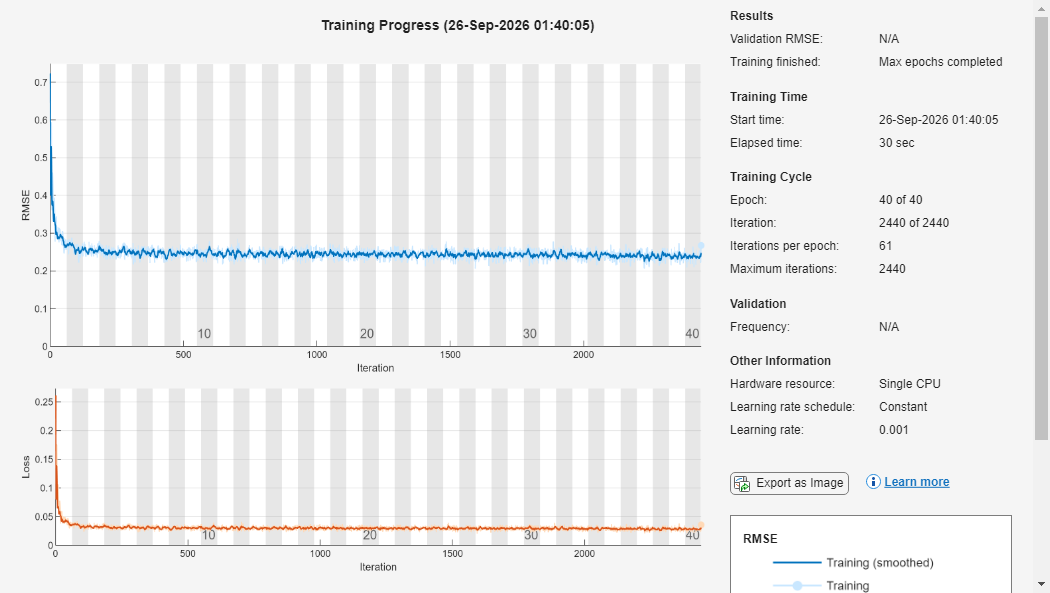

neural_net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


load("datasets\testing_dataset.mat")

You need to apply the same preprocessing steps as you did for your training data

### B) Filter the data

Refer to **Step 3** of the **Preprocessing** section in **Notebook 2**.

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Added what we did for filtering in notebook 02

sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 750; % Change this random value

filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter
ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = FilterX(b, a, testing_data.raw_neural_data, ch_init_conds);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### C) Generate neural features from the testing dataset

Refer to the **Feature Extraction** section in **Notebook 2.**

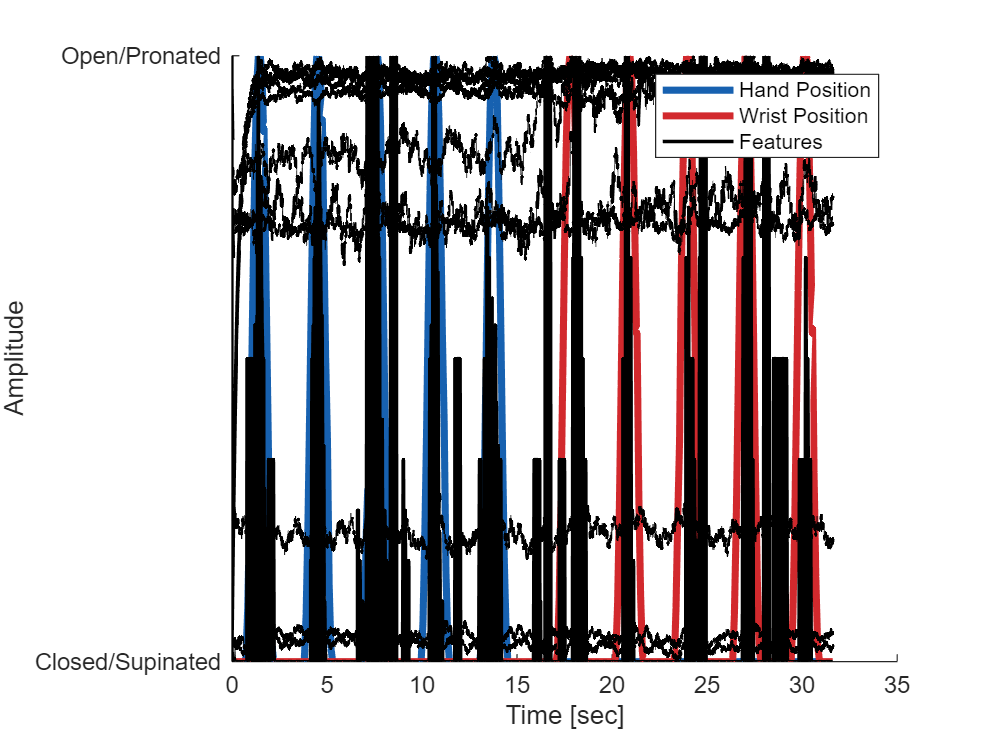

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Build test features with the SAME methods as training
%
% IMPORTANT: The results/features_*.mat training files must match this pipeline.


load("results\features_binned_test.mat")
load("results\features_SES_test.mat")
load("results\features_RMS_test.mat")
load("results\features_ZC_test.mat")
load("results\features_ZCR_test.mat")
load("results\features_combo_test.mat")

test_features_binned = neural_features_binned_test;
test_features_SES = neural_features_SES_test;
test_features_RMS = neural_features_RMS_test;
test_features_ZC = neural_features_ZC_test;
test_features_ZCR = neural_features_ZCR_test;
test_features_combo = neural_features_combo_test;

assert(length(test_features_binned) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
assert(length(test_features_SES) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
assert(length(test_features_RMS) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
assert(length(test_features_ZC) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
assert(length(test_features_ZCR) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
assert(length(test_features_combo) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

% look at the selected features vs kinematics
plot_features(testing_data, normalize(test_features_combo, "range", [0 1]));

test_features_all = struct("binned", test_features_binned, "SES", test_features_SES, ...
                            "RMS", test_features_RMS, "ZC", test_features_ZC, "ZCR", test_features_ZCR, ...
                            "combo", test_features_combo);
test_neural_features_raw = test_features_all.(feature_type);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(size(test_neural_features_raw, 2) == numel(feat_lo), ...
    "Test feature width must match training feature width for this feature_type")
% Apply TRAIN min/max
test_neural_features = (test_neural_features_raw - feat_lo) ./ feat_span;


fprintf("Test features '%s': size=%s  mean=%.4g  std=%.4g\\n", ...
    feature_type, mat2str(size(test_neural_features)), ...
    mean(test_neural_features(:)), std(test_neural_features(:)));


### D) Reshape the neural features

Refer to **Step 3** of **Notebook 3**

% Match training downsample and network input size
if ~exist("ds", "var")
    ds = 30;
end
test_neural_features = test_neural_features(1:ds:end, :);
kinematics_observed = testing_data.hand_kinematics(1:ds:end, :);

% feature dim must match the trained network
net_in = neural_net.Layers(1).InputSize; % [H W C]

Test features 'combo': size=[948198 30]  mean=0.2903  std=0.3921\n

assert(width(test_neural_features) == net_in(1), ...
    sprintf("Feature width %d != network input height %d. Retrain with the same feature_type.", ...
            width(test_neural_features), net_in(1)));

n_features = width(test_neural_features);
n_timestamps = size(test_neural_features, 1);
image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps], "like", test_neural_features);
for timestamp = 1:n_timestamps
    reshaped_features(:, 1, 1, timestamp) = test_neural_features(timestamp,:)';
end
fprintf("Reshaped test input: %s\n", mat2str(size(reshaped_features)));

### E) Predict the testing kinematics based on your generated features

kinematics_predicted = predict(neural_net, reshaped_features);
kinematics_predicted = double(squeeze(kinematics_predicted));
% N x 2 (observations x DoF)
if size(kinematics_predicted, 2) ~= size(kinematics_observed, 2)
    kinematics_predicted = kinematics_predicted';
end
assert(isequal(size(kinematics_predicted), size(kinematics_observed)), ...
    sprintf("Pred size %s != observed size %s", ...
        mat2str(size(kinematics_predicted)), mat2str(size(kinematics_observed))));

rmse = sqrt(mean((kinematics_predicted - kinematics_observed).^2, 1));
corr_hand = corr(kinematics_predicted(:,1), kinematics_observed(:,1));

Reshaped test input: [30 1 1 31607]


corr_wrist = corr(kinematics_predicted(:,2), kinematics_observed(:,2));
fprintf("TEST RMSE hand=%.4f wrist=%.4f | corr hand=%.3f wrist=%.3f\n", ...
    rmse(1), rmse(2), corr_hand, corr_wrist);
fprintf("Pred std hand=%.4f wrist=%.4f (near-zero std means flat/useless predictions)\n", ...
    std(kinematics_predicted(:,1)), std(kinematics_predicted(:,2)));

### D) Compare your predictions with the actual values of the kinematics

figure
tlo = tiledlayout(2, 1);
t = (0:size(kinematics_observed,1)-1)' / (testing_data.sample_rate / ds);

nexttile
hold on
plot(t, kinematics_observed(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 2.5)
plot(t, kinematics_predicted(:,1), 'LineStyle','-','Color', "#000000", 'LineWidth', 1.25)
hold off

TEST RMSE hand=0.1224 wrist=0.2356 | corr hand=0.915 wrist=0.656


grid on
ylim([-0.05 1.05])

Pred std hand=0.2476 wrist=0.2087 (near-zero std means flat/useless predictions)


xlabel("Time [sec]")
ylabel("Hand Position")
title(sprintf("Hand | RMSE=%.3f | corr=%.3f", rmse(1), corr_hand))
legend(["Observed", "Predicted"], "Location", "best")

nexttile
hold on
plot(t, kinematics_observed(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 2.5)
plot(t, kinematics_predicted(:,2), 'LineStyle','-','Color', "#000000", 'LineWidth', 1.25)
hold off
grid on
ylim([-0.05 1.05])
xlabel("Time [sec]")
ylabel("Wrist Position")
title(sprintf("Wrist | RMSE=%.3f | corr=%.3f", rmse(2), corr_wrist))
legend(["Observed", "Predicted"], "Location", "best")

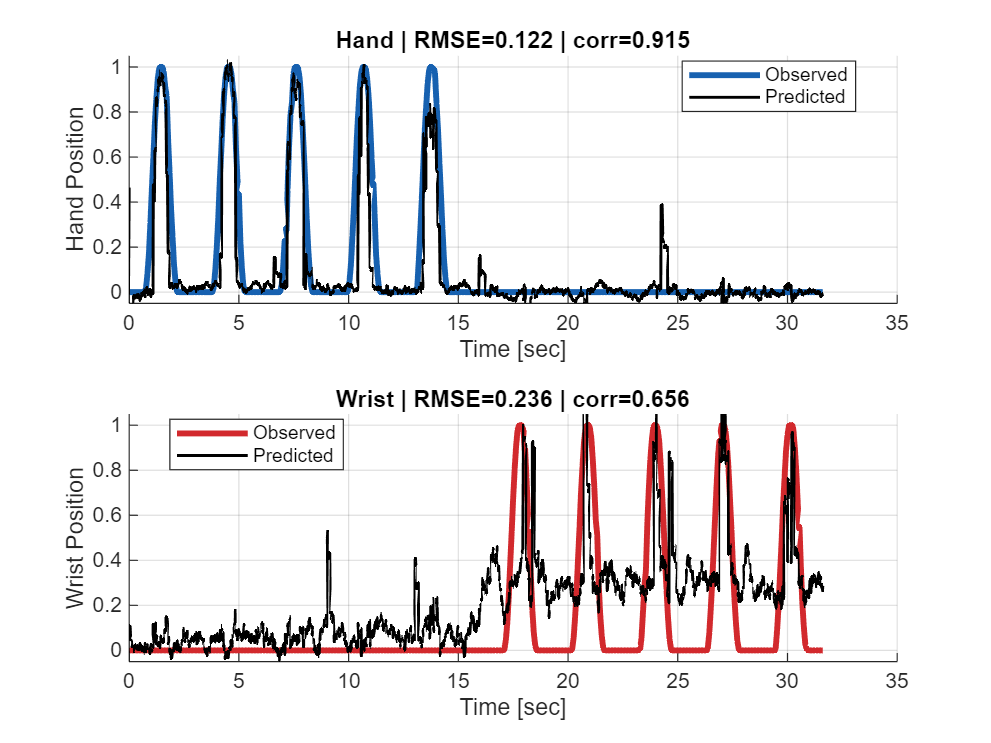

% Helper Functions
function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')

end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))

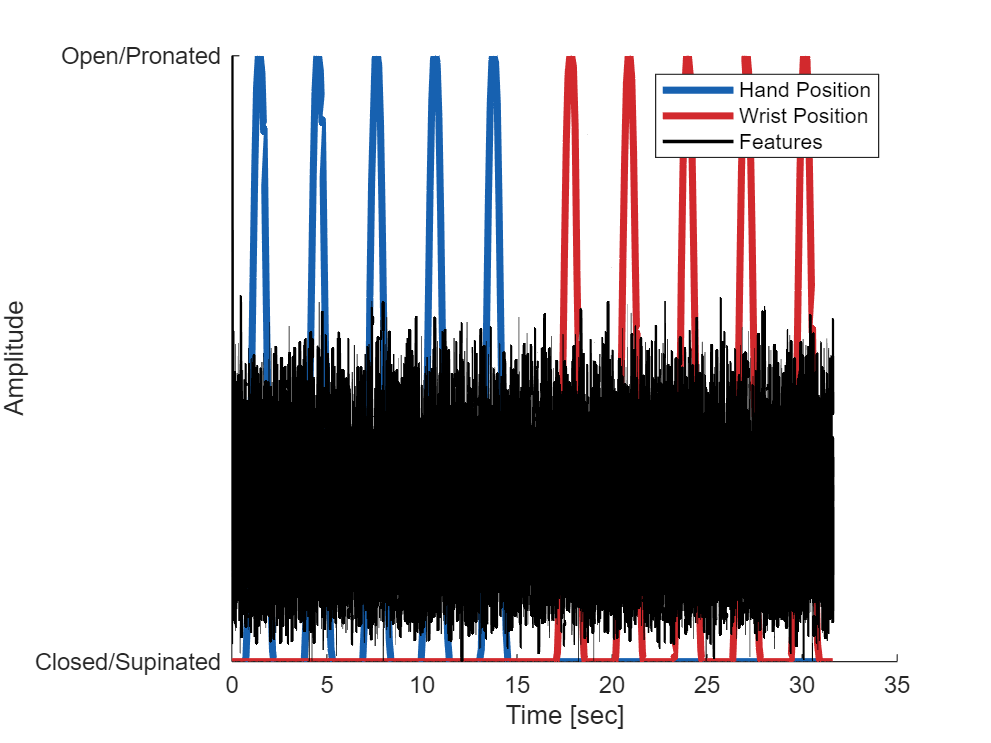

    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.Color = "black";
raster_handle.LineProperties(1).Color = "#0072BD";
raster_handle.LineProperties(2).Color = "red";
raster_handle.DisplayLabels = ["Hand Position", "Wrist Position", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));


    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan)])
    subtitle(['Spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end

function fig_handle = plot_features(training_data, neural_features)
fig_handle = figure;
hold on
t = (0:1:length(training_data.hand_kinematics)-1)/training_data.sample_rate;
plot(t, training_data.hand_kinematics(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(t, training_data.hand_kinematics(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(t, neural_features,'Color',"#000000" ,'LineWidth', 1.5)
hold off
box off
ylim([0 1])
yticks([0 1])
yticklabels({"Closed/Supinated", "Open/Pronated"})
xlabel("Time [sec]")
ylabel("Amplitude")
legend(["Hand Position", "Wrist Position", "Features"])
end
